Sun

diameter $1\ldotp 39*{10}^9 \;\;m$

Blackbody temperature of 5760K

the sun disk forms an angle of 32 min of a degree.

Hydrogen is converted to Helium

The sun’s total energy output is 3.8 � 1020 MW, which is equal to 63 MW/m2 of the sun’s surface.

the sun rotates around its axis about once every 4 weeks.

# Equation of Time


$$\textrm{�}$$



$$B=\left(N-81\right)\frac{360}{364}$$


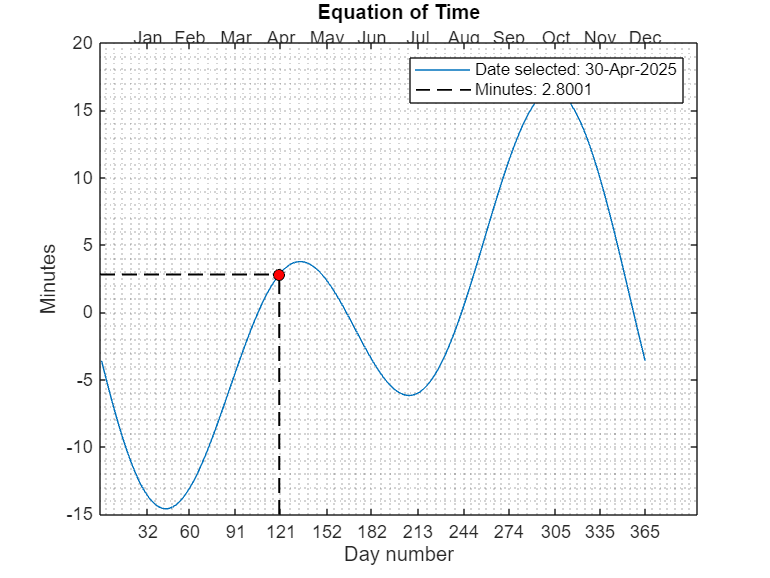

dateSelected = datetime("2025-04-30", "InputFormat", "uuuu-MM-dd");
ET = EoTfcn("doy", dateSelected, "plotswitch", true);

### Longitude Correction

LST = 10.5;
LL = -89.4;
LL = 33.33;
% LL = -99.13;

AST = ASTfcn(LST, ET, LL);

AST = 365×1 datetime array
   10:39
   10:39
   10:38
   10:38
   10:37
   10:37
   10:37
   10:36
   10:36
   10:35
   10:35
   10:35
   10:34
   10:34
   10:34
   10:33
   10:33
   10:33
   10:32
   10:32
   10:32
   10:31
   10:31
   10:31
   10:31
   10:30
   10:30
   10:30
   10:30
   10:29


output= createTable(AST, "Name", 'Apparent Solar Time, AST')

output = 365×2 table
       Date        Apparent Solar Time, AST
    ___________    ________________________

    01-Jan-2025             10:39          
    02-Jan-2025             10:39          
    03-Jan-2025             10:38          
    04-Jan-2025             10:38          
    05-Jan-2025             10:37          
    06-Jan-2025             10:37          
    07-Jan-2025             10:37          
    08-Jan-2025             10:36          
    09-Jan-2025             10:36          
    10-Jan-2025             10:35          
    11-Jan-2025             10:35          
    12-Jan-2025             10:35          
    13-Jan-2025             10:34          
    14-Jan-2025             10:34          
    15-Jan-2025             10:34          
    16-Jan-2025             10:33          


### Declination, $\delta$

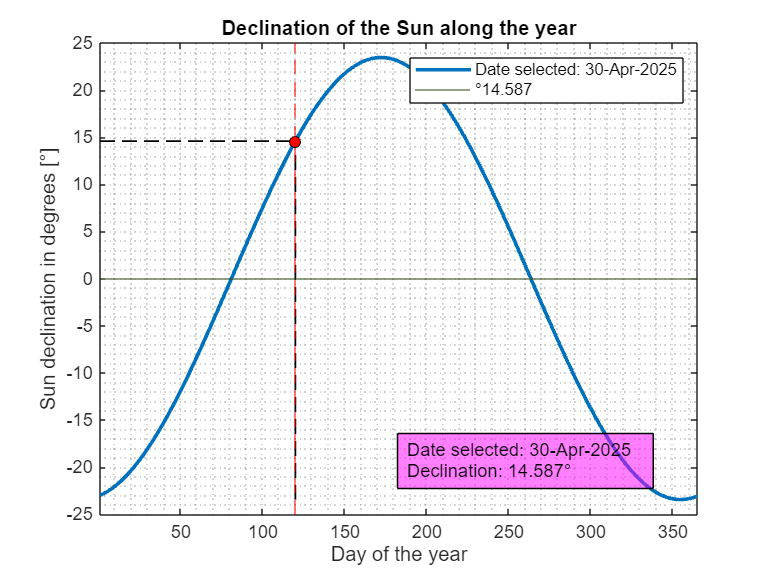

[delta, declination_plot] = solarDeclinationfcn(dateSelected,"plotswitch", true);